%% 按照之前的想法，对每张图片进行平均
session_idxall{1} = [14:16, 1:13];
%session_idxall{2} = [1:13, 16, 15, NaN];%使用了第五天的数据用来代替
session_idxall{2} = [1:13, 16, 15, 14];
%session_idxall{3} = [1:14, NaN, 16];
session_idxall{3} = [1:14, 15, 16];
session_idxall{4} = [1:14, 16, 15,17];
session_idxall{5} = [1:16];

% 初始化数据结构
all_data = cell(1, 17);
for condition = 1:17
    all_data{condition} = cell(1, 1405);
    for y = 1:1405
        all_data{condition}{2, y} = 0; % 初始化计数
    end
end

% 遍历每一天的数据
for dayday = 1:5
    session_idx = session_idxall{dayday};
    ori_idx = cell(length(session_idx), 1);
    
    % 遍历每个会话
    for session = 1:length(session_idx)
        
        if ~isnan(session_idx(session))
            % 加载数据
            load(sprintf('/home/dclab2/Ensemble coding/data/12%02ddata/DG2-u78%d-%03d-500Hz.mat', dayday + 8, dayday + 1, session - 1));
            trailnum = 6916;
            TrialStimID = reshape(Datainfo.Seq.StimID,[52, trailnum / 52])';
            RealOrdid = [];
            RealOrdbuffid = TrialStimID;
            RealOrdbufferrorid = [];
            
            % 处理响应代码
            for kk = 1:length(Datainfo.VSinfo.sMbmInfo.respCode)
                RealOrdid = [RealOrdid; RealOrdbuffid(kk, :)];
                if Datainfo.VSinfo.sMbmInfo.respCode(kk) ~= 1
                    RealOrdbuffid = cat(1, RealOrdbuffid, RealOrdbuffid(kk, :));
                end
            end
            
            RealTrialID = find(Datainfo.VSinfo.sMbmInfo.respCode == 1);
            StimID = RealOrdid(RealTrialID, :);
            StimID = StimID';
            
            % 根据会话类型处理刺激ID
            ori = processStimID(StimID, session_idx(session));
            ori_idx{session} = ori;

            % 初始化方向数据
            orientation_data = cell(2, 1405);
            for i = 1:1405
                orientation_data{1,i} = zeros(96,101);
                orientation_data{2,i} = 0;
            end
            for trial = 1:133
                for block = 1:4
                    window = (100 + 260 * (block - 1) + 1):(100 + 260 * (block - 1) + 1 + 100);
                    
                    % 计算基线和MUA
                    baseline = squeeze(mean(Datainfo.trial_MUA{2}(trial, 1:96, 1:100), 3));
                    MUA = squeeze(Datainfo.trial_MUA{2}(trial, 1:96, window)) - baseline';
                    orientation = StimID(1 + 13 * (block - 1), trial);
                    
                    % 将MUA数据存入方向数据
                    if isempty(orientation_data)
                        orientation_data{1, orientation} = MUA;
                    else
                        orientation_data{1, orientation} = orientation_data{1, orientation}+MUA;
                    end
                    
                    orientation_data{2, orientation} = orientation_data{2, orientation}+1;
                end
            end
            
            % 更新 all_data
            % updateAllData(all_data, session_idx(session), orientation_data);
            session_idxreal=session_idx(session);
            for y = 1:1405
                if ~isempty(orientation_data{1,y})
                    if isempty(all_data{session_idx(session)}{1,y})
                        all_data{session_idxreal}{1,y} = orientation_data{1,y};
                    else
                        all_data{session_idxreal}{1,y} = orientation_data{1,y}+all_data{session_idxreal}{1,y};
                    end
                    all_data{session_idxreal}{2,y} = all_data{session_idxreal}{2,y}+orientation_data{2,y};
                end
            end
            clearvars -except all_data session session_idx ori_idx session_idxall dayday
            disp(session);
        end
        
    end
end

% 函数：处理刺激ID

% %only decoding EC
% ECdata = cat(3,all_data{1,14}{1,1:18});
% a = 1;
% ori = 1;
% for i = 1:6
%     num = all_data{1,14}{2,1+(i-1)*3+(ori-1)*18}+all_data{1,14}{2,2+(i-1)*3+(ori-1)*18}+all_data{1,14}{2,3+(i-1)*3+(ori-1)*18};
%     
%     labels(a:(a+num)-1)=i;
%     a = a +num;
% end
for time = 1:101
% 1. 数据准备
data = squeeze(ECdata1(:,time,:))'; % 示例特征矩阵


% 2. 数据标准化

y = labels1'; % 分类标签

% 数据标准化
X = (data - mean(data, 1)) ./ std(data, 0, 1); % 标准化



% 设置超参数搜索范围
kernelOptions = {'linear', 'rbf'}; % 核函数选项
boxConstraintValues = [0.1, 1, 10]; % 约束参数选项
bestAccuracy = 0; % 存储最佳准确率

% 遍历不同超参数组合
for kernelIdx = 1:length(kernelOptions)
    for boxIdx = 1:length(boxConstraintValues)
        % 当前核函数和约束参数
        kernelFunc = kernelOptions{kernelIdx};
        boxConstraint = boxConstraintValues(boxIdx);

        % 创建 SVM 模板
        svmTemplate = templateSVM('KernelFunction', kernelFunc, 'BoxConstraint', boxConstraint);

        % 使用 fitcecoc 构建多分类模型，并进行 5 折交叉验证
        svm_model_cv = fitcecoc(X, y, 'Learners', svmTemplate, ...
            'Coding', 'onevsall', 'CrossVal', 'on', 'KFold', 5);

        % 计算交叉验证的分类准确率
        cv_accuracy = 1 - kfoldLoss(svm_model_cv);

        %fprintf('Kernel: %s, BoxConstraint: %.2f, Accuracy: %.2f%%\n', ...
%                 kernelFunc, boxConstraint, cv_accuracy * 100);

        % 更新最佳模型
        if cv_accuracy > bestAccuracy
            bestAccuracy(time) = cv_accuracy;
            bestModel{time} = svm_model_cv; % 存储最佳模型
        end
    end
end

% 输出最佳模型的准确率
fprintf('最佳模型的交叉验证准确率: %.2f%%\n', bestAccuracy(time) * 100);
end



figure;
load('/home/dclab2/Ensemble coding/data/chanmap.mat');
for coil = 1:96
    n = find(ChanMap==coil);
    subplot(10,10,n)
    
    for condition = 14:16
        hold on
        data1 = zeros(1,101);
        for ori = 1:18
            data0 = zeros(1,101);
            if condition >14
                for repeat = 1:6
                    data0 = data0+all_data{1,condition}{1,ori+(repeat-1)*18}(coil,:);
                    data1 = data1+all_data{1,condition}{1,ori+(repeat-1)*18}(coil,:);
                end
            elseif condition <14
                for repeat = 1:6
                    data0 = data0+all_data{1,condition}{1,ori+(repeat-1)*18+(condition-1)*108}(coil,:);
                    data1 = data1+all_data{1,condition}{1,ori+(repeat-1)*18+(condition-1)*108}(coil,:);
                end
            else
                for repeat = 1:6

                    data_repeat1=squeeze(mean(all_data{1,condition}{1,1+(ori-1)*18+(repeat-1)*3}(coil,:,:),3));
                    data_repeat2=squeeze(mean(all_data{1,condition}{1,2+(ori-1)*18+(repeat-1)*3}(coil,:,:),3));
                    data_repeat3=squeeze(mean(all_data{1,condition}{1,3+(ori-1)*18+(repeat-1)*3}(coil,:,:),3));
                    data_pic = data_repeat1+data_repeat2+data_repeat3;
                    data0 = data0+data_pic/3;
                end
                data1 = data1+data0;
            end
            %plot(smooth(data0),'Color',[0.5,0.5,0.5]);
        end
        plot(smooth(data1/18),'LineWidth',2)
    end
    
    subtitle(coil)
end

%对每张图片的统计
num = zeros(16,108);
for condition = 1:16
    for i = 1:108
        if condition >14
            num(condition,i) = all_data{1,condition}{2,i};
        elseif condition <14
            num(condition,i) = all_data{1,condition}{2,i+(condition-1)*108};

        else
            num1 = all_data{1,condition}{2,1+(i-1)*3};
            num2 = all_data{1,condition}{2,2+(i-1)*3};
            num3 = all_data{1,condition}{2,3+(i-1)*3};
            num(condition,i) = num1+num2+num3;
        end
        data1 = data1+data0;
        %plot(smooth(data0),'Color',[0.5,0.5,0.5]);
    end
    plot(smooth(data1/18),'LineWidth',2)
end


figure;
hold on;

% 定义颜色
colorcluster = [150,195,125;47, 127, 193; 216, 56, 58; 243, 210, 102] / 256;

% 用于存储高斯曲线的句柄
plotHandles = gobjects(1, 3);

% 绘制直方图和高斯曲线
for condition = [13,14:16]
    % 绘制直方图
    h = histogram(num(condition, :), 'Normalization', 'pdf', 'BinWidth', 2, 'EdgeColor', 'none');
    h.FaceColor = colorcluster(condition - 12, :);
end

for condition = [13,14:16]
    % 拟合高斯分布
    pd = fitdist(num(condition, :)', 'Normal'); % 对数据拟合正态分布
    mu = pd.mu;                   % 获得均值
    sigma = pd.sigma;             % 获得标准差

    % 生成高斯分布曲线
    x = linspace(min(num(condition, :)), max(num(condition, :)), 100); % 从数据范围生成点
    y = normpdf(x, mu, sigma);              % 计算高斯分布的概率密度

    % 绘制高斯分布曲线，并存储句柄
    plotHandles(condition - 12) = plot(x, y, '-', 'LineWidth', 2, 'Color', colorcluster(condition - 12, :));
end

% 添加图例，仅针对高斯分布曲线
legend(plotHandles, {'Patch','EC', 'SC', 'EC0'}, 'Location', 'best');

% 添加标题和坐标轴标签
title('Repeats Num in Condition');
ylabel('PDF');

% 设置坐标轴样式
ax = gca;
set(ax, 'Box', 'off'); % 确保边框被去掉
ax.Box = 'off';

hold off;

% 计算均值和标准误差
figure;
data_set = {EC_data,SC_data,EC0_data};
load('/home/dclab2/Ensemble coding/data/chanmap.mat');
for coil = 1:96
    n = find(ChanMap==coil);
    subplot(10,10,n)
    for i = [2,3,1]
        hold on
        data = squeeze(data_set{i}(:,coil,:))';
        mean_data = mean(data, 2); % 沿列方向计算均值 (108x1)
        std_data = std(data, 0, 2); % 沿列方向计算标准差 (108x1)
        N = size(data, 2); % 样本数量 (列数)
        SEM = std_data / sqrt(N); % 标准误差

        % 计算 95% 置信区间
        z = 1.96; % 正态分布下 95% 的 Z 值
        CI_upper = mean_data + z * SEM; % 上置信界限
        CI_lower = mean_data - z * SEM; % 下置信界限

        % 绘制均值曲线和置信区间
        x = 1:size(data, 1); % 横轴 (即矩阵的行数)



        % 绘制置信区间为填充区域
        fill([x, fliplr(x)], [CI_upper', fliplr(CI_lower')], colorcluster(i+1,:), ...
            'EdgeColor', 'none', 'FaceAlpha', 0.5); % 灰色阴影，透明度 50%

        % 绘制均值曲线
        plot(x, mean_data, 'LineWidth', 2,"Color",colorcluster(i+1,:)); % 蓝色均值曲线
    end
    hold off
    subtitle(coil);
end


% 添加图例和标签
%最大值的位置
data_latency = zeros(3,96);
for coil = 1:96
    for i = 1:3
        [a,b] = max(squeeze(mean(data_set{i}(:,coil,:),1)));
        data_latency(i,coil)=b;
    end

end


coil_no = setdiff(1:96,coil_select(1:32));
data = data_latency(:,coil_no)'; % 转置矩阵，使每列为一个组

% 绘制箱型图
figure;
boxplot(data, 'Labels', {'EC', 'SC','EC0'});
hold on
% 设置每个箱型图的颜色
colors = colorcluster(2:4,:);  % 绿色
h = findobj(gca, 'Tag', 'Box');

for j = 1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(j, :), 'FaceAlpha', 0.5);

end


% 统计检验：单因素方差分析 (ANOVA)
[p, tbl, stats] = anova1(data, [], 'off'); % ANOVA 检验，'off' 表示不显示默认表格

% 如果显著性水平 p < 0.05，则两组之间存在显著性差异
if p < 0.05
    % 获取多重比较的结果
    result = multcompare(stats, 'Display', 'off'); % 多重比较（Tukey's HSD）

    % 遍历比较结果，标注显著性
    for i = 1:size(result, 1)
        group1 = result(i, 1); % 第一组索引
        group2 = result(i, 2); % 第二组索引
        p_value = result(i, 6); % 检验的 p 值

        % 如果 p 值小于显著性阈值（如 0.05 或 0.01），则标注
        if p_value < 0.05
            % 确定两组箱型图的 x 坐标
            x1 = group1;
            x2 = group2;

            % 确定两组箱型图的 y 坐标范围
            y_max1 = max(data(:, group1));
            y_max2 = max(data(:, group2));
            y_max = max(y_max1, y_max2) + 0.3; % 稍微上移，避免与箱型图重叠

            % 绘制连线
            plot([x1, x2], [y_max, y_max], 'k-', 'LineWidth', 1.5);

            % 添加显著性符号
            if p_value < 0.001
                text(mean([x1, x2]), y_max + 0.1, '***', 'HorizontalAlignment', 'center', 'FontSize', 12);
            elseif p_value < 0.01
                text(mean([x1, x2]), y_max + 0.1, '**', 'HorizontalAlignment', 'center', 'FontSize', 12);
            elseif p_value < 0.05
                text(mean([x1, x2]), y_max + 0.1, '*', 'HorizontalAlignment', 'center', 'FontSize', 12);
            end
        end
    end
end

hold off;


## 条件解码

[~,coilidx] = sort(coilSNR,'descend');

coilidx1 = coilidx(1:20)';
coilnum = length(coilidx1);
EC_data = zeros(108,coilnum,101);
SC_data = zeros(108,coilnum,101);
EC0_data = zeros(108,coilnum,101);
allpatch_data = zeros(108,coilnum,101);
patch13=zeros(108,coilnum,101);
EC20_data = zeros(108,coilnum,101);
EC_coding = zeros(108,coilnum,101);
EC0_coding = zeros(108,coilnum,101);
for i = 1:108
    for location = 1:12
        for coil = 1:coilnum
            data = smooth(all_data{1,location}{1,i+(location-1)*108}(coilidx(coil),:)/all_data{1,location}{2,i+(location-1)*108});  
            allpatch_data(i,coil,:) = squeeze(allpatch_data(i,coil,:))+data;
        end
    end
end

for i = 1:108
    EC1 = all_data{1,14}{1,(i-1)*3+1};
    EC2 = all_data{1,14}{1,(i-1)*3+2};
    EC3 = all_data{1,14}{1,(i-1)*3+3};
    num = all_data{1,14}{2,(i-1)*3+1}+all_data{1,14}{2,(i-1)*3+2}+all_data{1,14}{2,(i-1)*3+3};
    EC = (EC1+EC2+EC3)/num;
    EC20_1 = EC20{1,(i-1)*3+1};
    EC20_2 = EC20{1,(i-1)*3+2};
    EC20_3 = EC20{1,(i-1)*3+3};
    num20 = EC20{2,(i-1)*3+1}+EC20{2,(i-1)*3+2}+EC20{2,(i-1)*3+3};
    EC20name = (EC20_1+EC20_2+EC20_3)/num20;
    for coil =1:coilnum
        EC20_data(i,coil,:) = smooth(EC20name(coilidx(coil),:));
        EC_data(i,coil,:) = smooth(EC(coilidx(coil),:));
        SC_data(i,coil,:) = smooth(all_data{1,15}{1,i}(coilidx(coil),:)/all_data{1,15}{2,i});
        EC0_data(i,coil,:) = smooth(all_data{1,16}{1,i}(coilidx(coil),:)/all_data{1,16}{2,i});
        patch13(i,coil,:) = smooth(all_data{1,13}{1,i+108*12}(coilidx(coil),:)/all_data{1,13}{2,i+12*108});
        EC_coding(i,coil,:) = smooth(EC_fit(i,coilidx(coil),:));
        EC0_coding(i,coil,:) = smooth(EC0_fit(i,coilidx(coil),:));
    end
end

for i = 1:108
    for coil = 1:coilnum
        max1 = max(EC0_data(i,coil,:));
        max2 = max(allpatch_data(i,coil,:));
        allpatch_datanew(i,coil,:) = allpatch_data(i,coil,:)/max2*max1;
    end
end

%ll
for condition = 1:13
    for i = 1:108
        data{condition}{1,i} = all_data{1,condition}{1,i+(condition-1)*108}/all_data{1,condition}{2,i+(condition-1)*108};
    end
end
for i = 1:108
    data{14}{1,i} = all_data{1,16}{1,i}/all_data{1,16}{2,i};
end
for i = 1:108
    data{15}{1,i} = zeros(96,101);
    dd1 = all_data{1,14}{1,(i-1)*3+1}/all_data{1,14}{2,(i-1)*3+1};
    dd2 = all_data{1,14}{1,(i-1)*3+2}/all_data{1,14}{2,(i-1)*3+2};
    dd3 = all_data{1,14}{1,(i-1)*3+3}/all_data{1,14}{2,(i-1)*3+3};
    data{15}{1,i} = (dd1+dd2+dd3)/3;
    
end

y_fit = zeros(108,96,101);
idx1 = repmat(1:18,6,1)';
idx2 = repmat(0:18:90,18,1);
idx = reshape((idx1+idx2)',1,[]);
fit_condition = 14;
for trail = 1:108
    for coil = 1:96
        % 示例数据
        y = data{1,fit_condition}{1,trail}(coil,:)';      % 目标向量
        X = [];
        for condition = 1:12
            if fit_condition == 14
                X = cat(2,X,data{1,condition}{1,trail}(coil,:)');     % 候选向量矩阵
            else
                X = cat(2,X,data{1,condition}{1,idx(trail)}(coil,:)');
            end
        end

        % 超参数
        alpha = 0.001; % 学习率
        max_iter = 1000; % 最大迭代次数
        tol = 1e-6; % 收敛判定阈值

        % 初始化权重w
        w_opt = rand(12, 1) * 0.1; % 随机初始化权重


        % 梯度下降求解
        for iter = 1:max_iter
            % 计算误差和梯度
            error = y - X * w_opt;
            grad = -2 * X' * error;

            % 更新权重
            w_opt = w_opt - alpha * grad;

            % 检查收敛条件
            if norm(grad) < tol
                %disp(['梯度下降在第 ', num2str(iter), ' 次迭代后收敛']);
                break;
            end
        end

        % 用求解的权重计算拟合信号
        y_fit(trail,coil,:) = X * w_opt;

        % 显示结果
        %disp('最优权重w_opt (梯度下降):');
        %disp(w_opt);

        % 计算拟合误差
        error = norm(y - squeeze(y_fit(trail,coil,:))); % 欧几里得范数（L2 范数）
        %disp(['拟合误差 (梯度下降): ', num2str(error)]);
        WEC(trail,coil,:) = w_opt;
        accuracyEC(trail,coil) = 1 - 2 * sum((y - squeeze(y_fit(trail,coil,:))).^2) / sum(y.^2 + squeeze(y_fit(trail,coil,:)).^2);
    end
end



%

%简略归一化


% figure;
% for coil = 1:coilnum
%     subplot(6,6,coil)
%     plot(squeeze(mean(allpatch_datanew(:,coil,:),1)));
%     hold on 
%     plot(squeeze(mean(EC_data(:,coil,:),1)));
%     plot(squeeze(mean(EC0_datanew(:,coil,:),1)));
%     plot(squeeze(mean(EC20_data(:,coil,:),1)));
%     subtitle(coilidx1(coil))
% end


data_all = cat(4,cat(4,EC_data,EC0_data),SC_data);
a = min(min(min(min(data_all))));
b = max(max(max(max(data_all))));
for i = 1:108
    for coil = 1:96
        for time = 1:101
            for condition = 1:3
                data_all_norm(i,coil,time,condition) = (data_all(i,coil,time,condition)-a)/(b-a);
                
            end
        end
    end
end
EC_data_norm = data_all(:,coil_select,:,1);
EC0_data_norm = data_all(:,coil_select,:,2);
SC_data_norm = data_all(:,coil_select,:,3);

labels1 = reshape(repmat(1:18,6,1),1,[]);
%labels2 = reshape(repmat(1:18,6,1)',[],1);


% labels1 = ones(108, 1);     % 数据集1的标签为1
% labels2 = ones(108, 1) * 2; % 数据集2的标签为2
% labels3 = ones(108, 1) * 3; % 数据集3的标签为3
time_length = 50;
ks= 10;
% 合并数据和标签
data = EC_data(:,:,1:time_length); % 合并所有数据
labels = labels1'; % 合并所有标签
SVMModel = cell(ks,time_length);
accuracy = zeros(ks,time_length);
for k = 1:10
    cv = cvpartition(labels, 'HoldOut', 0.2); % 80% 训练，20% 测试
    % 将数据重塑为二维矩阵，每行一个样本，每列一个特征
    num_samples = size(data, 1);
    num_channels = size(data, 2);
    num_timepoints = size(data, 3);
    cluster(k,:) = training(cv);
    for time = 1:time_length
        % 取每个通道在时间上的均值作为特征
        features = squeeze(data(:,:,time)); % size(features) 为 [324, 96]
        % 划分训练集和测试集

        trainData = features(training(cv), :);
        trainLabels = labels(training(cv));
        testData = features(test(cv), :);
        testLabels = labels(test(cv));
        % 训练 SVM 分类器
        SVMModel{k,time} = fitcecoc(trainData, trainLabels);

        % 对测试数据进行预测
        predictions = predict(SVMModel{k,time}, testData);
        % 评估模型准确率
        accuracy(k,time) = sum(predictions == testLabels) / length(testLabels);
        disp(['Model Accuracy: ', num2str(accuracy(k,time) * 100), '%']);
    end
end


对过去数据的解码


testLabels = reshape(repmat(1:18,416,1),1,[]);
for ori = 1:18
    for k = 1:10
        for time = 1:50
            predictions = predict(SVMModel{k,time}, squeeze(MUA_all{1,1}(:,time,:))');
            accuracy(ori,k,time) = sum(predictions == testLabels((ori-1)*416+1)) / 416;
            disp(['Model Accuracy: ', num2str(accuracy(k,time) * 100), '%']);
        end
    end
end

## 动图

% 清空所有内容
 close all;

% 数据准备2


% 动图参数设置
filename = 'animated_plot.gif'; % 保存的 GIF 文件名
frame_delay = 1; % 每帧持续时间（单位：秒）
num_curves = 18;
% 创建图形窗口
figure;
hold on;
grid on;
title('动态曲线绘制');
xlabel('X 轴');
ylabel('Y 轴');
xlim([0, 2*pi]); % 设置 x 轴范围
ylim([-1.5, 1.5]); % 设置 y 轴范围

% 初始化绘图
h = plot(NaN, NaN, 'b', 'LineWidth', 2); % 初始化一个空的绘图对象

% 动图绘制循环
for i = 1:num_curves
    % 更新曲线数据
    h.XData = 1:50;
    h.YData = a(i, 50);
    
    % 暂停 1 秒以模拟每秒绘制
    pause(0.5); 
    
    % 获取当前帧并保存为 GIF
    frame = getframe(gcf); % 获取当前图形窗口的帧
    img = frame2im(frame); % 将帧转换为图像
    [imind, cm] = rgb2ind(img, 256); % 将图像转换为索引图像（GIF 格式要求）
    
    % 保存到 GIF 文件
    if i == 1
        % 如果是第 1 帧，创建 GIF 文件
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', frame_delay);
    else
        % 如果是后续帧，追加到 GIF 文件
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', frame_delay);
    end
end


### 做图片刺激响应的相关性

idx1 = repmat(1:18,6,1)';
idx2 = repmat(0:18:90,18,1);
idx = reshape((idx1+idx2)',1,[]);


EC0_datanew = EC0_data(idx,:,:);
allpatch_datanew = allpatch_datanew(idx,:,:);
SC_datanew = SC_data(idx,:,:);
patch13_datanew = patch13(idx,:,:);
EC0_codingnew = EC0_coding(idx,:,:);
window1 = 1:30;
window2 = 31:60;
m1 = EC_data(:,:,1:30);
m2 = EC_data(:,:,31:60);
n1 = EC0_datanew(:,:,1:30);
n2 = EC0_datanew(:,:,31:60);
EC1  = (m1-min(m1(:)))/(max(m1(:))-min(m1(:)));
EC2  = (m2-min(m2(:)))/(max(m2(:))-min(m2(:)));
EC01  = (n1-min(n1(:)))/(max(n1(:))-min(n1(:)));
EC02  = (n2-min(n2(:)))/(max(n2(:))-min(n2(:)));

numMatrices = 108*4;
% 初始化相关性矩阵
correlationMatrix = zeros(numMatrices, numMatrices);
dataset = cat(1,EC1,EC01);
dataset = cat(1,dataset,EC2);
dataset = cat(1,dataset,EC02);
%dataset = cat(1,dataset,EC_coding(:,:,21:50));
% dataset = cat(1,dataset,EC0_codingnew(:,:,window1));
% dataset = cat(1,dataset,SC_datanew(:,:,window1));
dataset = cat(1,dataset,allpatch_datanew(:,:,window1));
% dataset = cat(1,dataset,EC20_data);

% 两两计算相关性
for i = 1:numMatrices
    for j = i:numMatrices % 只计算上三角部分，提高效率
        
        % 将矩阵展开为向量
        vector1 = reshape(squeeze(dataset(i,:,:)), [], 1); % 将第 i 个矩阵拉平成向量
        vector2 = reshape(squeeze(dataset(j,:,:)), [], 1); % 将第 j 个矩阵拉平成向量
        
        % 计算相关性
        correlationMatrix(i, j) = corr(vector1, vector2); % 皮尔逊相关性
        correlationMatrix(j, i) = correlationMatrix(i, j); % 对称性
    end
    %disp(i);
end

% 输出相关性矩阵
%disp(correlationMatrix);

% 可视化相关性矩阵
figure;
imagesc(correlationMatrix); % 显示相关性矩阵
colorbar;


### MDS降维

% Step 1: 生成相关性矩阵或加载你的相关性矩阵
n = numMatrices; % 矩阵大小


a = colormap('jet');
coloridx = 1:14:256;
% Step 2: 将相关性矩阵转换为距离矩阵
dist_matrix = sqrt(max(0, 1 - correlationMatrix.^2)); % 确保非负
dist_matrix(1:n+1:end) = 0; % 设置对角线为零

% Step 3: 执行 MDS 降维
dim = 3; % 投影到三维
[Y, stress] = mdscale(dist_matrix, dim); % Y 是投影后的坐标，stress 是误差

% Step 4: 计算每个维度的解释方差比例
% 原始距离的平方和（总方差）
total_variance = sum(dist_matrix(:).^2);
    
% 计算每个维度的捕捉方差
variance_dim1 = sum(pdist(Y(:, 1)).^2); % 第一维的方差
variance_dim2 = sum(pdist(Y(:, 2)).^2); % 第二维的方差
variance_dim3 = sum(pdist(Y(:, 3)).^2); % 第三维的方差

% 计算解释比例
explained_dim1 = variance_dim1 / total_variance; % 第一维解释比例
explained_dim2 = variance_dim2 / total_variance; % 第二维解释比例
explained_dim3 = variance_dim3 / total_variance; % 第三维解释比例

% 打印解释比例
disp(['第一维解释比例: ', num2str(explained_dim1 * 100), '%']);

第一维解释比例: 43.9913%


disp(['第二维解释比例: ', num2str(explained_dim2 * 100), '%']);

第二维解释比例: 2.4152e-08%


disp(['第三维解释比例: ', num2str(explained_dim3 * 100), '%']);

第三维解释比例: 2.0696e-08%


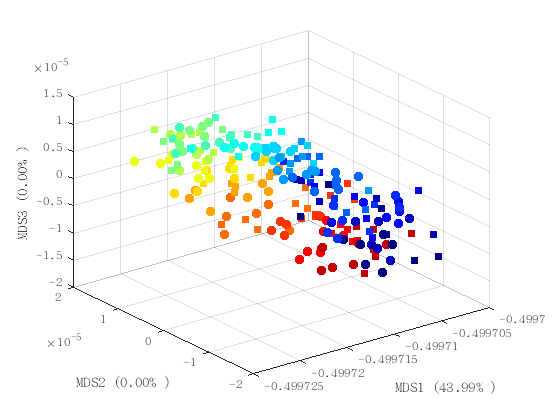


% Step 5: 绘制三维散点图
figure;
for ori = 1:18
scatter3(Y((ori-1)*6+1:ori*6, 1), Y((ori-1)*6+1:ori*6, 2), Y((ori-1)*6+1:ori*6, 3), 50, a(coloridx(ori),:), 'filled', 'Marker', 's'); % 前一半点为红色

hold on;

scatter3(Y(108+((ori-1)*6+1:ori*6), 1), Y(108+((ori-1)*6+1:ori*6), 2), Y(108+((ori-1)*6+1:ori*6), 3), 50, a(coloridx(ori),:), 'filled', 'Marker', 'o'); % 前一半点为红色
%scatter3(Y(12+((ori-1)*6+1:ori*6), 1), Y(12+((ori-1)*6+1:ori*6), 2), Y(12+((ori-1)*6+1:ori*6), 3), 50, a(coloridx(ori),:), 'filled','Marker', '^'); % 后一半点为蓝色
% scatter3(Y(18+((ori-1)*6+1:ori*6), 1), Y(18+((ori-1)*6+1:ori*6), 2), Y(18+((ori-1)*6+1:ori*6), 3), 50, a(coloridx(ori),:), 'Marker', '+'); % 后一半点为蓝色
% scatter3(Y(432+((ori-1)*6+1:ori*6), 1), Y(432+((ori-1)*6+1:ori*6), 2), Y(432+((ori-1)*6+1:ori*6), 3), 50, a(coloridx(ori),:), 'Marker', '*'); % 后一半点为蓝色
end
% 设置三维图的标题和标签

xlabel(sprintf('MDS1 (%.2f%% )', explained_dim1 * 100));
ylabel(sprintf('MDS2 (%.2f%% )', explained_dim2 * 100));
zlabel(sprintf('MDS3 (%.2f%% )', explained_dim3 * 100));



view(3); % 设置为 3D 视角
hold off;

### 组间的相关性

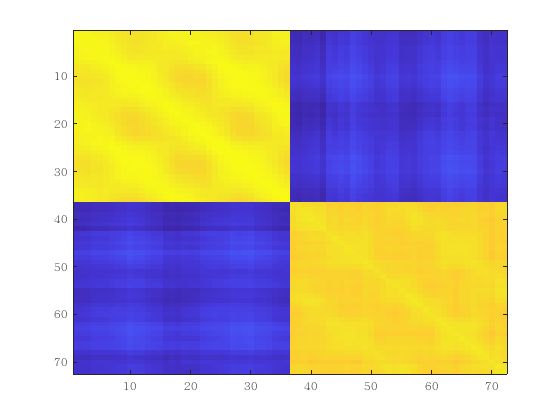

clusternum = n/6;
newmatrix = zeros(clusternum,clusternum);
for cluster1 = 1:clusternum
    for cluster2 = 1:clusternum
        data = correlationMatrix((cluster1-1)*6+1:cluster1*6,((cluster2-1)*6+1:cluster2*6));
        newmatrix(cluster1,cluster2) = mean(data(:));
    end
end
figure;
imagesc(newmatrix);

% Step 1: 生成相关性矩阵或加载你的相关性矩阵





% Step 2: 将相关性矩阵转换为距离矩阵
dist_matrix = sqrt(max(0, 1 - newmatrix.^2)); % 确保非负
dist_matrix(1:clusternum+1:end) = 0; % 设置对角线为零
dist_matrix = (dist_matrix + dist_matrix') / 2; 
% Step 3: 执行 MDS 降维
dim = 3; % 投影到三维
[Y, stress] = mdscale(dist_matrix, dim); % Y 是投影后的坐标，stress 是误差

% Step 4: 计算每个维度的解释方差比例
% 原始距离的平方和（总方差）
total_variance = sum(dist_matrix(:).^2);

% 计算每个维度的捕捉方差
variance_dim1 = sum(pdist(Y(:, 1)).^2); % 第一维的方差
variance_dim2 = sum(pdist(Y(:, 2)).^2); % 第二维的方差
variance_dim3 = sum(pdist(Y(:, 3)).^2); % 第三维的方差

% 计算解释比例
explained_dim1 = variance_dim1 / total_variance; % 第一维解释比例
explained_dim2 = variance_dim2 / total_variance; % 第二维解释比例
explained_dim3 = variance_dim3 / total_variance; % 第三维解释比例

% 打印解释比例
disp(['第一维解释比例: ', num2str(explained_dim1 * 100), '%']);
disp(['第二维解释比例: ', num2str(explained_dim2 * 100), '%']);
disp(['第三维解释比例: ', num2str(explained_dim3 * 100), '%']);

% Step 5: 绘制三维散点图
figure;
for ori = 1:18
scatter3(Y(ori, 1), Y(ori, 2), Y(ori, 3), 50, a(coloridx(ori),:), 'filled', 'Marker', 's'); % 前一半点为红色
hold on;
scatter3(Y(18+ori, 1), Y(18+ori, 2), Y(18+ori, 3), 50, a(coloridx(ori),:), 'filled', 'Marker', 'o'); % 前一半点为红色
% scatter3(Y(36+ori, 1), Y(36+ori, 2), Y(36+ori, 3), 50, a(coloridx(ori),:), 'filled','Marker', '^'); % 后一半点为蓝色
% scatter3(Y(54+ori, 1), Y(54+ori, 2), Y(54+ori, 3), 50, a(coloridx(ori),:), 'filled','Marker', 'd'); 
% scatter3(Y(72+ori, 1), Y(72+ori, 2), Y(72+ori, 3), 50, a(coloridx(ori),:),'Marker', '+'); 
end
% 设置三维图的标题和标签

xlabel(sprintf('MDS1 (%.2f%% )', explained_dim1 * 100));
ylabel(sprintf('MDS2 (%.2f%% )', explained_dim2 * 100));
zlabel(sprintf('MDS3 (%.2f%% )', explained_dim3 * 100));

plot3(Y([19:36,19],1),Y([19:36,19],2),Y([19:36,19],3),'-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r','color',[0.1,0.1,0.1]*5)
plot3(Y([1:18,1],1),Y([1:18,1],2),Y([1:18,1],3),'-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r','color',[0.1,0.1,0.1]*3)
% plot3(Y([37:54,37],1),Y([37:54,37],2),Y([37:54,37],3),'-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r','color',[0.1,0.1,0.1]*8)
% plot3(Y([55:72,55],1),Y([55:72,55],2),Y([55:72,55],3),'-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r','color',[0.1,0.1,0.1]*9)
% plot3(Y([73:90,73],1),Y([73:90,73],2),Y([73:90,73],3),'-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r','color',[0.1,0.1,0.1]*1)
view(3); % 设置为 3D 视角
hold off

% Step 3: 执行 MDS 降维
dim = 2; % 投影到二维
[Y, stress] = mdscale(dist_matrix, dim); % Y 是投影后的坐标，stress 是误差

% Step 4: 计算每个维度的解释方差比例
% 原始距离的平方和（总方差）
total_variance = sum(dist_matrix(:).^2);

% 计算每个维度的捕捉方差
variance_dim1 = sum(pdist(Y(:, 1)).^2); % 第一维的方差
variance_dim2 = sum(pdist(Y(:, 2)).^2); % 第二维的方差

% 计算解释比例
explained_dim1 = variance_dim1 / total_variance; % 第一维解释比例
explained_dim2 = variance_dim2 / total_variance; % 第二维解释比例
% 不再计算第三维的解释比例

% 打印解释比例
disp(['第一维解释比例: ', num2str(explained_dim1 * 100), '%']);
disp(['第二维解释比例: ', num2str(explained_dim2 * 100), '%']);

% Step 5: 绘制二维散点图
figure;
for ori = 1:18
    scatter(Y(ori, 1), Y(ori, 2), 50, a(coloridx(ori),:), 'filled', 'Marker', 's'); % 前一半点为红色
    hold on;
    scatter(Y(18+ori, 1), Y(18+ori, 2), 50, a(coloridx(ori),:), 'filled', 'Marker', 'o'); % 后一半点为红色
end

% 设置二维图的标题和标签
xlabel(sprintf('MDS1 (%.2f%% )', explained_dim1 * 100));
ylabel(sprintf('MDS2 (%.2f%% )', explained_dim2 * 100));

% 如果需要可以添加连接线
plot(Y([19:36,19],1), Y([19:36,19],2), '-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'color', [0.1,0.1,0.1]*5);
plot(Y([1:18,1],1), Y([1:18,1],2), '-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'color', [0.1,0.1,0.1]*3);

hold off; % 结束绘制

## 投射平面

% 示例输入：两组 3D 点
figure;
a = colormap('jet');
coloridx = 1:14:256;
a = a(coloridx,:);
for i = 1:2
points1 = Y((i-1)*18+1:i*18,:); % 第一组点
 % 第二组点（偏移增加 1，以与第一组点区分）
% 示例输入：两组 3D 点


hold on;
grid on;

% 计算第一组点的最佳拟合平面及其圆
[normal, d] = bestFitPlane(points1);
[center, radius] = calculateCircle(points1, normal, d);
radius
n=i;
theta = linspace(0, 2 * pi, 100);

% 定义圆在平面上的初始方向
v = null(normal'); % 找到与法向量正交的两个方向
circlePoints = (center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta)))';


if n == 1 
    plotCircle(normal, center, radius, [130,176,210]/256);
    for ori = 1:18
    
    scatter3(points1(ori,1), points1(ori,2), points1(ori,3), 50, a(ori,:), 'filled', 'Marker', 'o','DisplayName', 'Points Group 1');
    end
    circlePoints1 = (center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta)))';
else
    plotCircle(normal, center, radius, [255,190,122]/256);
    for ori = 1:18
    
    scatter3(points1(ori,1), points1(ori,2), points1(ori,3), 50, a(ori,:), 'filled', 'Marker', 's');
    end
    circlePoints2 = (center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta)))';
end





        

rotate3d on;

end

radius = 1.2257e-05

radius = 1.0596e-05

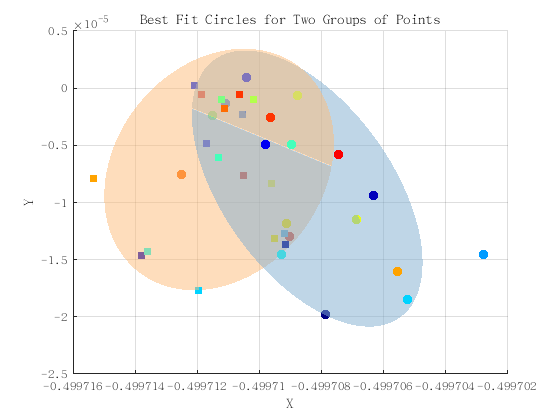

% 图形设置
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Best Fit Circles for Two Groups of Points');

P1 = circlePoints1;  % 示例矩阵 P1
P2 = circlePoints2;  % 示例矩阵 P2
% 利用所有点拟合平面，计算法向量
% P1 和 P2 分别是平面 1 和平面 2 的点集 (100×3)

% 平面 1 拟合
[~, ~, V1] = svd(bsxfun(@minus, P1, mean(P1, 1)), 0); % SVD 分解
n1 = V1(:, end)'; % 平面 1 的法向量 (取右奇异向量)

% 平面 2 拟合
[~, ~, V2] = svd(bsxfun(@minus, P2, mean(P2, 1)), 0); % SVD 分解
n2 = V2(:, end)'; % 平面 2 的法向量 (取右奇异向量)

% 计算法向量的夹角
cos_theta = dot(n1, n2);  % 点积计算余弦值
cos_theta = max(min(cos_theta, 1), -1); % 限制范围
theta = acos(cos_theta);  % 弧度
theta_degrees = rad2deg(theta); % 转角度

% 输出结果
disp(['两个平面之间的夹角（角度）：', num2str(theta_degrees), '°']);

两个平面之间的夹角（角度）：15.2478°


% 1. 拟合平面 1 的方程
[~, ~, V1] = svd(bsxfun(@minus, P1, mean(P1, 1)), 0); % SVD 拟合
n1 = V1(:, end)'; % 法向量 (平面 1)
D1 = -dot(n1, mean(P1, 1)); % 平面 1 常数项

% 2. 拟合平面 2 的方程
[~, ~, V2] = svd(bsxfun(@minus, P2, mean(P2, 1)), 0); % SVD 拟合
n2 = V2(:, end)'; % 法向量 (平面 2)
D2 = -dot(n2, mean(P2, 1)); % 平面 2 常数项

% 3. 检查平面是否平行
if abs(dot(n1 / norm(n1), n2 / norm(n2)) - 1) < 1e-6
    % 平行平面，计算距离
    d = abs(D2 - D1) / norm(n1);
    disp(['两个平面之间的距离为：', num2str(d)]);
else
    % 非平行平面，计算点到平面的最近距离
    % 计算 P1 到 P2 点集的平均距离
    distances = abs(P1 * n2' + D2) / norm(n2); % P1 上点到平面 2 的距离
    avg_distance = mean(distances);
    disp(['两个平面之间的平均距离为：', num2str(avg_distance)]);
end

两个平面之间的平均距离为：2.1287e-06


## 曲面连接

figure;
for i = 1:3:10
% 假设 circle1 和 circle2 是两组圆的三维坐标
circle1 = ppfactor.circlePoints{i,1}; % 第一个圆的坐标
circle2 = ppfactor.circlePoints{i+3,1}; % 第二个圆的坐标


% 创建一个曲面
% 将两个圆的坐标组合成一个曲面
X = [circle1(:, 1); circle2(:, 1)]; % x坐标
Y = [circle1(:, 2); circle2(:, 2)]; % y坐标
Z = [circle1(:, 3); circle2(:, 3)]; % z坐标

% 创建一个曲面
% 定义三角形的顶点索引
triangles = [1:100; 101:200; mod(1:100, 100) + 1]'; % 连接两个圆的外边缘

% 绘制曲面

trisurf(triangles, X, Y, Z, 'FaceColor', [130+i*5,176,210]/256, 'FaceAlpha', 0.5);

% 绘制圆的边缘
hold on;
% plot3(circle1(:, 1), circle1(:, 2), circle1(:, 3), 'r', 'LineWidth', 2); % 第一个圆
% plot3(circle2(:, 1), circle2(:, 2), circle2(:, 3), 'b', 'LineWidth', 2); % 第二个圆


xlabel('X');
ylabel('Y');
zlabel('Z');
title('连接两个圆的曲面');
grid on;
axis equal; % 等比例缩放坐标轴
end

## 曲面偏转

figure;
clearvars -except ppfactor
for i = 1:2:11
% 假设 A 和 B 是 100x3 的矩阵，分别包含两个圆的三维坐标
A1 = ppfactor.circlePoints{1,1}; % A 中的第一个圆
A2 = ppfactor.circlePoints{1,2};
B1 = ppfactor.circlePoints{i+1,1}; % B 中的第一个圆
B2 = ppfactor.circlePoints{i+1,2};% B 中的第二个圆

% === 1. 定义 A1 的平面 ===
% 选择 A1 中的三个点，计算 A1 的法向量
p1 = A1(1, :);
p2 = A1(2, :);
p3 = A1(3, :);
v1_A = p2 - p1;
v2_A = p3 - p1;
normal_A = cross(v1_A, v2_A); % 计算法向量
normal_A = normal_A / norm(normal_A); % 单位化

% === 2. 定义 B1 的平面 ===
% 选择 B1 中的三个点，计算 B1 的法向量
q1 = B1(1, :);
q2 = B1(2, :);
q3 = B1(3, :);
v1_B = q2 - q1;
v2_B = q3 - q1;
normal_B = cross(v1_B, v2_B); % 计算法向量
normal_B = normal_B / norm(normal_B); % 单位化

% === 3. 计算从 B1 平面到 A1 平面的旋转矩阵 ===
% 旋转轴为两个法向量的叉积
rotation_axis = cross(normal_B, normal_A);
rotation_axis = rotation_axis / norm(rotation_axis); % 单位化

% 旋转角度为两个法向量之间的夹角
rotation_angle = acos(dot(normal_B, normal_A));

% 构造旋转矩阵（使用 Rodrigues' 旋转公式）
K = [0, -rotation_axis(3), rotation_axis(2);
     rotation_axis(3), 0, -rotation_axis(1);
     -rotation_axis(2), rotation_axis(1), 0]; % 反对称矩阵
R = eye(3) + sin(rotation_angle) * K + (1 - cos(rotation_angle)) * (K * K); % 旋转矩阵

% === 4. 将 B1 和 B2 应用旋转变换 ===
% 将 B1 调整到与 A1 同一平面上
B1_adjusted = (R * B1')'; % 旋转每个点

% 同样旋转 B2，以保持相对位置关系
B2_adjusted = (R * B2')';

% === 5. 平移 B1 到与 A1 平面对齐 ===
% 调整 B1 的位置，使其与 A1 平面对齐（中心点对齐）
B1_center = mean(B1_adjusted, 1); % B1 的中心
A1_center = mean(A1, 1); % A1 的中心
translation_vector = A1_center - B1_center;
B1_adjusted = B1_adjusted + translation_vector;
B2_adjusted = B2_adjusted + translation_vector;

% === 可视化结果 ===

hold on;

% 绘制 A1
if i == 1
fill3(A1(:, 1), A1(:, 2), A1(:, 3), 'r', 'FaceAlpha', 0.5);
fill3(A2(:, 1), A2(:, 2), A2(:, 3), [10+i*20,176,210]/256, 'FaceAlpha', 0.5);
end
% 绘制调整后的 B1 和 B2
%fill3(B1_adjusted(:, 1), B1_adjusted(:, 2), B1_adjusted(:, 3), 'g', 'FaceAlpha', 0.5);
fill3(B2_adjusted(:, 1), B2_adjusted(:, 2), B2_adjusted(:, 3), [130+i*5,176,210]/256, 'FaceAlpha', 0.5);



end
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Adjusted B1 and B2 to Match A1 Plane');
grid on;

[d, Z, transform] = procrustes(Y1, Y2); % X1 为参考，X2 被对齐
Y = [Y1;Z];


var = 1;
for ori = 1:18
    
    datatype = newmatrix(ori,ori+18);
    if ori <=var
        datavar1 = newmatrix(ori,ori+var);
        datavar2 = newmatrix(ori,18+ori-var);
    elseif ori + var>=19
        datavar1 = newmatrix(ori,ori+var-18);
        datavar2 = newmatrix(ori,ori-var);
    else
        datavar1 = newmatrix(ori,ori+var);
        datavar2 = newmatrix(ori,ori-var);
    end
    
    mm(ori) = (datavar1+datavar2)/2-datatype;
end
new = newmatrix;
new(1:55:end)=0;
for i = 1:54
    [x,y] = max(new(i,:));
    hh(i)=y;
end

function ori = processStimID(StimID, session_idx)
    ori = [];
    if session_idx < 14
        % 处理 EC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 1405
                    ori(x, y) = mod(StimID(x, y) - (session_idx - 1) * 108, 18);
                    if ori(x, y) == 0
                        ori(x, y) = 18;
                    end
                else
                    ori(x, y) = 19;
                end
            end
        end
    elseif session_idx == 14
        % 处理 EC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 325
                    ori(x, y) = floor((StimID(x, y) - 1) / 18 + 1);
                else
                    ori(x, y) = 19;
                end
            end
        end
    else
        % 处理 SC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 109
                    ori(x, y) = mod(StimID(x, y), 18);
                    if ori(x, y) == 0
                        ori(x, y) = 18;
                    end
                else
                    ori(x, y) = 19;
                end
            end
        end
    end
end

% % 函数：更新 all_data
% function updateAllData(all_data, session_idxreal, orientation_data)
%     for y = 1405
%         if isempty(all_data{session_idxreal}{1,y}) 
%             all_data{session_idxreal}{1,y} = orientation_data{1,y};
%         else
%             all_data{session_idxreal}{1,y} = mean(orientation_data{1,y},3)+mean(all_data{session_idxreal}{1,y},3);
%         end
%         if ~isempty(orientation_data{1,y})
%             all_data{session_idxreal}{2,y} = all_data{session_idxreal}{2,y}+length(orientation_data{1,y});
%         end
%     end
% end
function [normal, d] = bestFitPlane(points)
    % 计算点的均值（质心）
    centroid = mean(points, 1);
    
    % 将点的坐标减去均值，得到相对于质心的坐标
    centeredPoints = points - centroid;
    
    % 计算协方差矩阵（点与质心偏移的内积）
    covMatrix = centeredPoints' * centeredPoints;
    
    % 计算协方差矩阵的特征值和特征向量
    [eigenvectors, eigenvalues] = eig(covMatrix);
    
    % 最小特征值对应的特征向量是平面的法向量
    [~, minIndex] = min(diag(eigenvalues));
    normal = eigenvectors(:, minIndex);
    
    % 计算平面方程中的 d 值
    d = -normal' * centroid';
end

% ========================
% 函数：计算拟合圆的中心和半径
% ========================
function [center, radius] = calculateCircle(points, normal, d)
    % 计算点到平面的投影
    numPoints = size(points, 1);
    projectedPoints = zeros(numPoints, 3);
    for i = 1:numPoints
        point = points(i, :);
        % 使用点积计算点到平面的距离
        distance = (dot(normal, point) + d) / norm(normal); % 点到平面的距离
        projectedPoints(i, :) = point - distance * normal'; % 投影点坐标
    end
    
    % 计算投影点的中心
    center = mean(projectedPoints, 1);
    
    % 计算每个投影点到中心的距离
    distances = vecnorm(projectedPoints - center, 2, 2);
    
    % 圆的半径是最大距离
    radius = max(distances);
end


% ========================
% 函数：在平面上绘制圆
% ========================
function plotCircle(normal, center, radius, color)
    % 定义圆的角度
    theta = linspace(0, 2 * pi, 100);
    
    % 定义圆在平面上的初始方向
    v = null(normal'); % 找到与法向量正交的两个方向
    circlePoints = (center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta)))';
    
    % 绘制圆
    fill3(circlePoints(:,1), circlePoints(:,2), circlePoints(:,3), color, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
end